clear;
close all;

## Setup

% Values that we're giving you
Fs = 4e6; % Sampling rate (samples/sec)
Rs = 50e3; % Symbol rate in symbols/sec (baud)
Tmax = 0.1; % Max time for the simulation (sec)
fc = 1e6; % Carrier frequency (Hz)
B = 350e3; % Bandwidth (Hz)

% Complete these expressions using the variables above
N = Fs*Tmax; % Total number of sample points in the simulation
Ns = Rs*Tmax; % Number of symbols to send
sps = Fs/Rs; % Number of samples per symbol

% Use these variables for plotting
t = linspace(0, Tmax-1/Fs, N); % Time vector
f = linspace(-Fs/2, Fs/2, N); % Frequency vector. Recall from 113 that DFT gives us -f/2 to +f/2

## Symbol Generation

Generate random set of bits of 0s and 1s

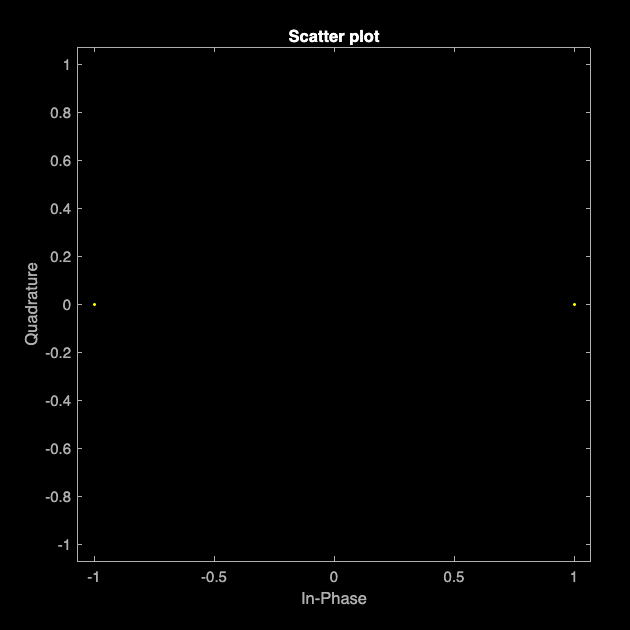

bits = randi([0, 1], 1, Ns);

% Map bits to BPSK symbols of -1s and 1s
symbs = 2 * (bits - 0.5);

% Plot BPSK constellation digram
scatterplot(symbs);

## Carrier Modulation

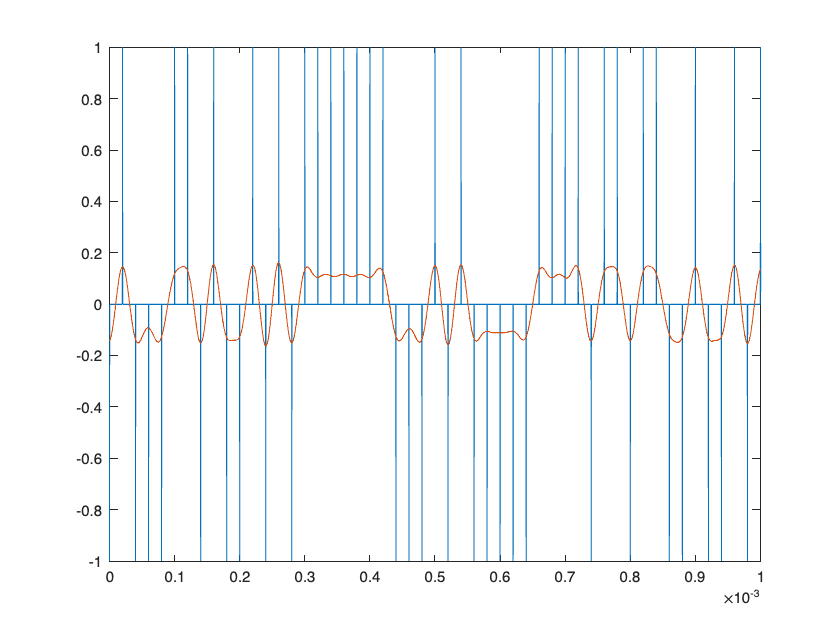

delta_train_symbs = upsample(symbs, sps);
figure
plot(t, delta_train_symbs);
xlim([0 0.001]);

rect_impulse = ones([1, sps]);
rect_filt = conv(delta_train_symbs, rect_impulse, "same"); 

roll_off = 0.5;
span = 10; % the number of symbols the impulse response of the RRC impulse response will last for
rrc_impulse = rcosdesign(roll_off, span, sps, "sqrt"); 
rrc_filt = conv(delta_train_symbs, rrc_impulse, "same"); 

hold on
plot(t, rrc_filt);


% Modulation
carrier = exp(-1i*fc*t);
analytic_sig = carrier .* rrc_filt;

ph_offset = unifrnd(0, 2*pi);
disp(["Phase: ", ph_offset]);

    "Phase: "    "3.4888"



Tx = real(analytic_sig * exp(-1i*ph_offset));


## Channel

channel_filter = "NONE";

if (channel_filter == "Tustin")
    s = tf('s');
    Hc = B*s/(s^2 + s*B + fc^2);
    Hd = c2d(Hc, 1/Fs, 'tustin');
    [a, b] = tfdata(Hd);
    analytic_sig = real(filter(a{:}, b{:}, analytic_sig));
else

end

% Gaussian noise
std_dev = 0.1;
noise = std_dev * randn(1, N); %var = std_dev^2
Rx = Tx + noise;

## Carrier Demodulation

Costas Loop

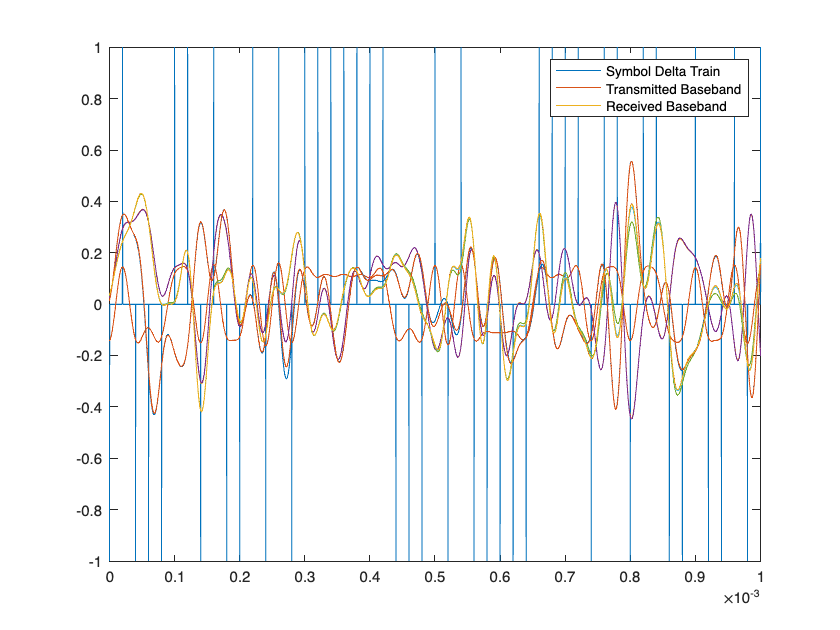

inph = zeros(1, N);
quad = zeros(1, N);
inph_ = zeros(1, N);
quad_ = zeros(1, N);

err = zeros(1, N);
ph = zeros(1, N+1);

f_offset = 0;
fr = fc + f_offset;

Kp =0.122;
Ki =0.001;
integrator = 0;

f = [0,0.2,0.4,1];
a = [1,1,0,0];
order = 5;
lp = firpm(order, f, a);
lp_length = length(lp);

% normalizeE?????

for idx =order+1:N
    
    nco_c = 2*cos(2*pi*fr*t(idx) + ph(idx));
    nco_s = -2*sin(2*pi*fr*t(idx) + ph(idx));

    % demodulate the signal by mixing with NCO signals
    inph_(idx) = Rx(idx) * nco_c;
    quad_(idx) = Rx(idx) * nco_s;    

    % low pass filter to get rid of high frequency components
    I = filter(lp, 1, inph_(idx-order:idx));
    Q = filter(lp, 1, quad_(idx-order:idx));
    inph(idx) = I(end);
    quad(idx) = Q(end);

    % mix in_ph and quad to get error signal
    err(idx) = inph(idx)*quad(idx);

    % NCO
    integrator = integrator + Ki * err(idx);
    ph(idx+1) = ph(idx)+Kp*err(idx)+integrator;

     % low pass filter to get rid of high frequency components
%     filt_in_phase = filter(lp, 1, rec_in_phase(prev_idx:idx));
%     filt_quad = filter(lp, 1, rec_quad(prev_idx:idx));
%     
%     err(idx) = filt_in_phase(end) * filt_quad(end);
%     integrator = integrator + err(idx);
%     new_phase = old_phase + Kp*err(idx) + Ki*integrator;
% 
%     ph(idx) = 

%     x = A' \ phase'; % matrix division -- that's a way of getting the slope?
%     slope = x(1);
%     if (abs(slope - phase(idx)/Fs) > 1e-5); disp("BAD"); end 

end

% p(t) conv with rrc
inph = -conv(inph, rrc_impulse, "same");

hold on 
plot(t, inph);
legend('Symbol Delta Train', 'Transmitted Baseband', 'Received Baseband');


% 1/10 symbol rate
% filter out the carrier signal
% f_cutoff = 5000; % not cut-off frequency should be somewhere between the bandwidth of the modulation and double the carrier frequency.

## Symbol Detection

rec_samples = inph(1:sps:N);

Unrecognized function or variable 'rec_in_phase'.

rec_bits = zeros([1, Ns]);
for i=1:Ns
    if (rec_samples(i) > 0); rec_bits(i) = 1; else; rec_bits(i) = 0; end
end

scatterplot(rec_samples);


total_err_plt = zeros(1, Ns);
total_err = 0;
for idx=1:Ns
    if (rec_bits(idx) ~= bits(idx))
        total_err = total_err + 1;
    end
    total_err_plt(idx) = total_err;
end
figure();
plot(1:Ns, total_err_plt);


% err_rate = sum(rec_bits ~= bits) / Ns;